# Kernel Ridge Regression

## Initailization (Dataset: GaussianData)

- Zscore normalization

data=zscore(csvread('GaussianData.csv'));
x=data(:,1:end-1);
y=data(:,end);

- Total number of data points

N=length(data);

- Visualization of the Data

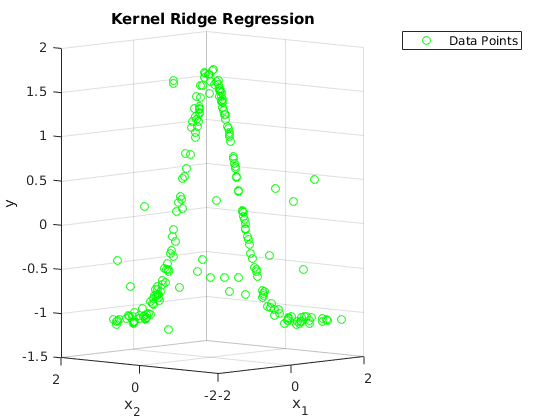

figure
scatter3(x(:,1),x(:,2),y,'g')
title('Kernel Ridge Regression')
xlabel({'x_1'})
ylabel({'x_2'})
zlabel('y')
view([-47.1 4.4])
legend('Data Points')

## Various Kernels for above data

- Linear Kernel

K_linear=(x*x');

- Polynomial Kernel (Poly3)

K_poly3=(x*x').^3;

- Gaussian Kernel

K_gauss=zeros(N,N);
for j=1:N
 for i=1:N
    K_gauss(i,j)=exp(-norm(x(j,:)-x(i,:)));
 end
end

## Algorithm

- f_linear : Regression Function due to Linear Kernel

- f_poly3 : Regression Function due to Poly3 Kernel

- f_gaussian : Regression Function due to Gaussian Kernel

- mse : Mean Square Error

- A\b instead of inv(A)*b for faster computation

f_linear=zeros(N,1);
f_poly3=zeros(N,1);
f_gaussian=zeros(N,1);

mse=[];
intvl=0.1;

for lambda=intvl:intvl:1
    
    for i=1:N
        
        f_linear(i,1)= y'*((K_linear+ lambda*eye(N))\K_linear(i,:)');
        
        f_poly3(i,1)= y'*((K_poly3+ lambda*eye(N))\K_poly3(i,:)');
        
        f_gaussian(i,1)= y'*((K_gauss+ lambda*eye(N))\K_gauss(i,:)');
    end
     
    mse=[mse; norm(f_linear-y)^2/N, norm(f_poly3-y)^2/N, norm(f_gaussian-y)^2/N];
end

## Mean square error is the assessment measure for optimal Kernel

mse_=min(mse(:,1));
fprintf('Mean square error (Linear Kernel) : %f',mse_)

Mean square error (Linear Kernel) : 0.992737


mse_=min(mse(:,2));
fprintf('Mean square error (Poly3 Kernel) : %f',mse_)

Mean square error (Poly3 Kernel) : 0.958541


[mse_,gaussain_indx]=min(mse(:,3));
fprintf('"minimum" Mean square error (Gaussian Kernel) : %f',mse_)

"minimum" Mean square error (Gaussian Kernel) : 0.027592

## Optimal Langrangian Parameter

lambda_optimal=intvl*gaussain_indx

lambda_optimal = 0.1000

## Prediction Values (due to various Kernels)

Predicted=[y,f_linear,f_poly3,f_gaussian]

Predicted =     0.1834   -0.0126    0.1303   -0.6786
   -1.0830    0.0042   -0.4274   -0.9423
   -1.0820   -0.0035   -0.2355   -0.8816
   -0.8228   -0.0510    0.1789   -0.5872
   -0.4720    0.0239   -0.0400   -0.0801
   -0.8747   -0.0285    0.0752   -0.7348
    1.3743    0.0913    0.4825    1.1210
    1.3125   -0.0984   -0.6370    0.5935
    1.4929   -0.0602   -0.1514    1.2063
   -0.0881   -0.0714    0.0839    0.0991


## Alpha & Dual, calculated as follows :

alpha=2*lambda_optimal*inv((K_gauss+lambda_optimal*eye(N)))*y

alpha =     0.7458
   -0.0496
   -0.2726
   -0.0627
   -0.7231
   -0.0772
    0.0979
    0.5878
    0.1432
   -0.0928


W_alpha=y'*alpha -(1/4*lambda_optimal)*alpha'*K_gauss*alpha -(1/4)*alpha'*alpha

W_alpha = 23.3498

## Actual Vs Predicted Values

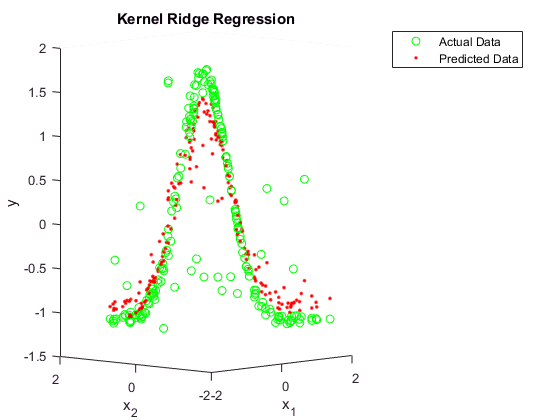

figure
hold on

scatter3(x(:,1),x(:,2),y,'g')
scatter3(x(:,1),x(:,2),f_gaussian,'.r')

title('Kernel Ridge Regression')
xlabel({'x_1'})
ylabel({'x_2'})
zlabel('y')
view([-47.1 4.4])
legend('Actual Data','Predicted Data')

hold off

% Bhartendu, Machine Learning & Computing